clear all
clear
close all

outputDirectory = '..\img';

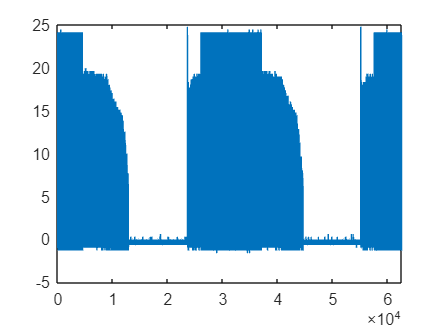



[timeVector1, voltageVector1] = importAgilentBin('./DriveLabSession4/scope_33.bin', 1);
[timeVector2, voltageVector2] = importAgilentBin('./DriveLabSession4/scope_33.bin', 2);

figure('Name','Phase A 1');
plot(voltageVector1);

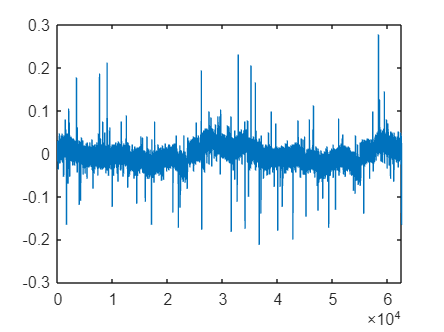

figure('Name','Phase A 2');
plot(voltageVector2);



[timeVector1, voltageVector1] = importAgilentBin('./DriveLabSession4/scope_38.bin', 1);
[timeVector2, voltageVector2] = importAgilentBin('./DriveLabSession4/scope_38.bin', 2);

figure('Name','Phase A 1');
t_ms = timeVector1 * 1000

t_ms =   -50.0001
  -50.0000
  -49.9999
  -49.9998
  -49.9997
  -49.9996
  -49.9995
  -49.9994
  -49.9993
  -49.9992


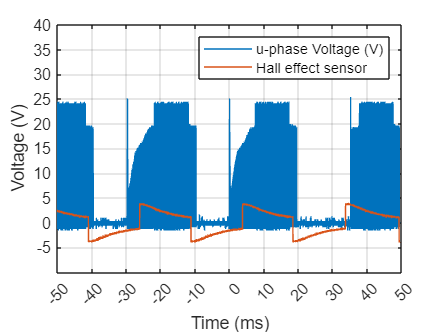

plot(t_ms, voltageVector1, t_ms, voltageVector2);
%figure('Name','Phase A 2');
%plot(voltageVector2);


grid on;
xticks(-50:10:50);
yticks(-5:5:40);
ylim([-10 40])
xlabel('Time (ms)');
ylabel('Voltage (V)');
legend(["u-phase Voltage (V)" "Hall effect sensor"])
saveas(gcf, fullfile(outputDirectory, 'sensorless_zero_crossings.png'));





[timeVector1, voltageVector2] = importAgilentBin('./DriveLabSession4/scope_33.bin', 1);
[timeVector2, voltageVector1] = importAgilentBin('./DriveLabSession4/scope_33.bin', 2);


figure('Name','Phase A Current 2');
t_ms = timeVector1 * 1000

t_ms =   -44.0625
  -44.0617
  -44.0609
  -44.0601
  -44.0593
  -44.0585
  -44.0577
  -44.0569
  -44.0561
  -44.0553


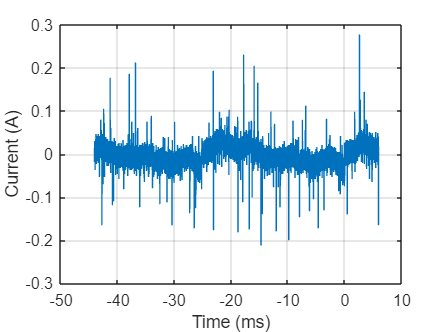

plot(t_ms, voltageVector1);
grid on;
xticks(-50:10:50);
xlabel('Time (ms)');
ylabel('Current (A)');
saveas(gcf, fullfile(outputDirectory, 'sensorless_current.png'));


figure('Name','Phase A Current 1');
plot(voltageVector2);


% Extract the time and data from the timeseries object
t = timeVector1;
x = voltageVector1;

% Compute the sampling frequency assuming equidistant time points
Fs = 1 / mean(diff(t));

thd_db = thd(x)

thd_db = -7.1746

percent_thd = 100*(10^(thd_db/20))

percent_thd = 43.7792

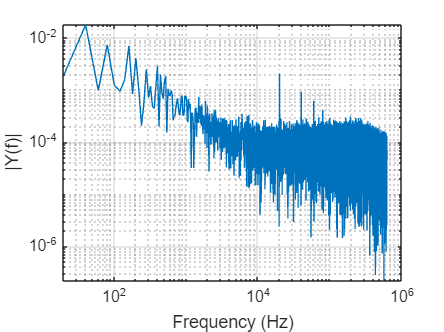

% Compute the FFT
Y = fft(x);

% Set DC component to 0 as we meassured to Uref
Y(1)=0;

% Compute the two-sided spectrum P2 and the single-sided spectrum P1
P2 = abs(Y / length(x));
P1 = P2(1:length(x)/2 + 1);
P1(2:end-1) = 2 * P1(2:end-1);

% Define the frequency domain f
f = Fs * (0:(length(x)/2)) / length(x);

% Plot single-sided amplitude spectrum
figure('Name','Single-Sided Amplitude Spectrum of A Current');
loglog(f, P1);
grid on;
xlabel('Frequency (Hz)');
ylabel('|Y(f)|');
saveas(gcf, fullfile(outputDirectory, 'sensorless_current_fft.png'));


[timeVector1, voltageVector1] = importAgilentBin('./DriveLabSession4/scope_39.bin', 1);
[timeVector2, voltageVector2] = importAgilentBin('./DriveLabSession4/scope_39.bin', 2);
% 
% start_idx = 145576 
% end_idx = 294538
% timeVector1 = timeVector1(start_idx:end_idx);
% timeVector2 = timeVector2(start_idx:end_idx);
% voltageVector1 = voltageVector1(start_idx:end_idx);
% voltageVector2 = voltageVector2(start_idx:end_idx);


bcvoltage = voltageVector1-voltageVector2;
figure('Name','Phase B-C');
t_ms = timeVector1 * 1000

t_ms =   -25.6251
  -25.6250
  -25.6249
  -25.6248
  -25.6247
  -25.6246
  -25.6245
  -25.6244
  -25.6243
  -25.6242


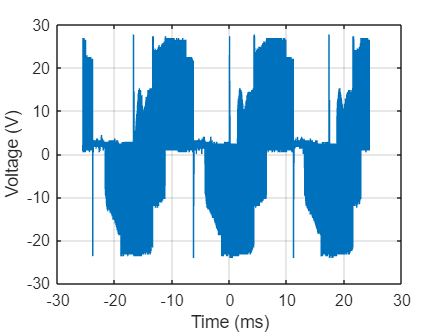

plot(t_ms, bcvoltage);
grid on;
xticks(-50:10:50);
xlabel('Time (ms)');
ylabel('Voltage (V)');
saveas(gcf, fullfile(outputDirectory, 'sensorless_voltage.png'));

% Extract the time and data from the timeseries object
t = timeVector1;
x = bcvoltage ;

% Compute the sampling frequency assuming equidistant time points
Fs = 1 / mean(diff(t));
thd_db = thd(x)

thd_db = -3.0833

percent_thd = 100*(10^(thd_db/20))

percent_thd = 70.1193

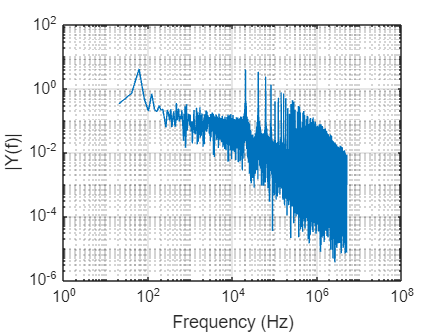

% Compute the FFT
Y = fft(x);

% Compute the two-sided spectrum P2 and the single-sided spectrum P1
P2 = abs(Y / length(x));
P1 = P2(1:length(x)/2 + 1);
P1(2:end-1) = 2 * P1(2:end-1);

% Define the frequency domain f
f = Fs * (0:(length(x)/2)) / length(x);

% Plot single-sided amplitude spectrum
figure;
title('Single-Sided Amplitude Spectrum of BC Phase');
loglog(f, P1);
grid on;
xlabel('Frequency (Hz)');
ylabel('|Y(f)|');

saveas(gcf, fullfile(outputDirectory, 'sensorless_voltageBC_fft.png'));


% cleanfigure;
% matlab2tikz(fullfile(outputDirectory, 'scope_20.tex'), 'showInfo', false);